# Machine Learning (ML) Theory

## What happens under the hood when we build a model?

- Understanding how ML algorithms work can help choose the appropriate model and parameters, and help interpret errors and model failure.

- Some models are transparent (e.g. regression) - we can see the underlying equations.

- Most ML algorithms are a "black box"

- Nevertheless, all ML can be considered a type of optimization.

- ML algorithms *optimize* for increased accuracy or reduced error.

## Cost function and optimization objective

- Optimzation refers to minimizing or maximizing a function *f(x) *by altering *x*. (*f(x)* is called the **objective function** or **cost function**)

- For example, if *x* is the value of blood glucose above which a patient is diabetic, and *f(x)* is the accuracy of identifying diabetic patients, then the goal of ML algorithm is to change *x *so that is optimizes *f(x)*.

## Finding the right cost function

- In some cases, the cost function is straightforward - e.g. reducing the error in classification of patients (diabetes vs normal).

- Sometimes it is difficult to decide what should be optimized. For example, should we measure the accuracy of binary classification (normal vs disease) or extent of the disease (stages of heart disease). Should we give partial credit for getting close to the right stage?

- Should we penalize small but frequent errors, or large but rare errors?

## Examples of cost functions

- For regression (most common): **MSE - Mean squared error**

$\mathrm{mean}\left(|Y-\mathrm{Ypred}|^{2\;} \right)\;$ or $\frac{\left({\mathrm{sum}\left(Y-\mathrm{Ypred}\right)}^2 \right)}{\mathrm{length}\left(Y\right)}$

- Regression: **MAE - Mean absolute error**


$$\mathrm{mean}\left(|Y-\mathrm{Ypred}|\right)$$


*MSE gives higher weight to large errors. In contrast, MAE increases linearly with error.

- For classification: **cross-entropy or log loss**


$$\left(y*\mathrm{log}\left(p\right)+\left(1-y\right)*\mathrm{log}\left(1-p\right)\right)$$
 

where *y *is 0 or 1, and *p *is the predicated probabilty (e.g. from logistic regression)

## How do we optimize the cost function?

- Calculus!

- In general, for building a ML model, we try to minimize an objective.

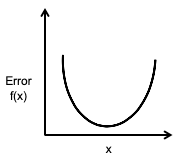

- The minimum of a function can be found using differentiation.

- Find* f'(x) *or *dy/dx*

- F(x) is minimum or maximum when *f'(x) = 0*

- Points where *f'(x) = 0 *are known as **critical points** or **stationary points**.

- A local minimum is a point where *f(x) *is lower than all neighboring points

## Finding minima using Gradient descent

- Make a small change to *x* and calculate *f(x)* and *f'(x)*. The value of slope tells you how to change *x*.

- In the gradient descent approach, the algorithm makes small changes in *x * with the opposite sign of the slope until you hit slope = 0.

- A point that obtains the absolute lowest value of *f(x)* is a global minimum.

- This approach can be scaled to multiple variables using partial derivatives.

## Gradient descent - parameters

- In practice, the algorithm may never hit zero precisely, but a very small number close zero (say 1E-6). We can enforce the number below which we can assume the slope to be zero (e.g. 1E-6). This number is called the **tolerance**.

- An important parameter in Gradient Descent is the **step size** or **learning rate**. If the learning rate is too small, then the algorithm will take a long time to find the minima. If the learning rate is too high, it might miss the minima and jump across the valley.

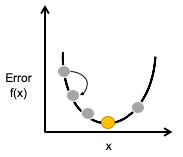

## Regression

- Consider a linear regression model to predict Y from X.

*Ypred = mX*

- The goal is to find "m" that best "fits" the data - i.e. minimizes the difference between Y and Ypred.

- Cost function - **Mean squared error (MSE):**


$$\mathrm{mean}\left(|Y-\mathrm{Ypred}|^{2\;} \right)\;$$
 

- The cost function changes as you change "m"

- Optimization goal: find "m" that minimizes MSE

- The best "m" is found by MATLAB using gradient descent

## Regularization

- Framework to reduce overfitting

- Idea: find the simplest model that explains the data.

- Penalize complexity - for example if a linear model with a single parameter does equally well as a quadratic model with two parameters, then the linear model is chosen.

- Hyperparameter (lambda, $\lambda$) - penalizes complexity

## Finding the best regularization model

- The optimization objective: Minimize MSE + Minimize regression coefficients

`min(MSE+lambda*beta)`

- If *lambda = 0,* then it is normal regression

- How to find the best *lambda*?

- Cross validation!

- Do cross validation on the training set.

## Regularization approach: Lasso regression

- **Lasso regression **penalizes model complexity; identifies the simplest model by removing correlated variables.

- Using lasso with 3-fold cross-validation to find the best lambda:

`[B, FitInfo] = lasso(X,Y,"CV",3);`

- Let's compare Traditional regression vs Lasso regression

## Test models using simulated data

- Simulated datasets are very useful for understanding how models work - since we know the right "answer" (i.e. the model that best explains the data, as we created the model).

- Let's create a simple linear model that's a function of 2 variables + 4 noise variables.

Regression coefficients; only 1st and 2nd are non-zero:

beta = [1;5;0;0;0;0]

beta =      1
     5
     0
     0
     0
     0


Create a random variable X from a normal distribution with mean 0 and variance 1:

X = normrnd(0,1,[50,6]);

Y = f(x) + noise:

y = X*beta + randn(50,1);

The number of columns of the 1st matrix must equal the number of rows of the 2nd matrix.

## Compare Traditional regression vs Lasso in simulated data

[B1, Fit] = lasso(X,y,"CV",10);

*Fit.IndexMinMSE* has the best lambda that has the lowest mean squared error during CV.

*Fit.Index1SE* has the sparsest model (with least number of predictors) within 1 standard deviation of the lowest error.

B1_coeff = B1(:,Fit.Index1SE)

B1_coeff =     0.5049
    4.7246
         0
         0
         0
         0


B1_intercept = Fit.Intercept(Fit.Index1SE)

B1_intercept = 0.2826

X_ones = [ones(length(X),1) X];
B2 = regress(y,X_ones)

B2 =     0.0916
    0.8954
    5.0637
    0.1299
   -0.0649
    0.0396
    0.0999


Which B is closer to the actual Betas used to generate Y?

Test accuracy of both methods using 3-fold cross validation.

% Create indices for 3-fold cross validation
indices = crossvalind("kfold",size(X,1),3);

% Initialize RMSE arrays
rmse_lasso = zeros(3,1);
rmse_regress = zeros(3,1);

for i = 1:3
    test = (indices == i);
    train = ~test;
    
    % Create X and y training sets (and X_ones for regress model)
    Xtrain = X(train,:);
    X_ones_train = X_ones(train,:);
    ytrain = y(train,:);
   
    % Lasso model
    [B1, Fit] = lasso(Xtrain,ytrain,"CV",10);
    B1_coeff = B1(:,Fit.Index1SE);
    B1_intercept = Fit.Intercept(Fit.Index1SE);
    
    % Normal regression model
    B2 = regress(ytrain,X_ones_train);
    
    % Create X and y test sets (and X_ones for regress model)
    Xtest = X(test,:);
    X_ones_test = X_ones(test,:);
    ytest = y(test,:);
    
    % Predicted values using model coefficients
    y_lasso = Xtest*B1_coeff + B1_intercept;
    y_regress = X_ones_test(:,2:end)*B2(2:end)+B2(1);
   
    % Calculate RMSE for each model
    rmse_lasso = sqrt(mean(y_lasso-ytest)^2);
    rmse_regress = sqrt(mean(y_regress-ytest)^2);
end
mean(rmse_lasso)

ans = 0.1693

mean(rmse_regress)

ans = 0.0053

## Stepwise regression

B3 = stepwisefit(X,y);

Initial columns included: none
Step 1, added column 2, p=1.05416e-29
Step 2, added column 1, p=1.23064e-06
Final columns included:  1 2 
    'Coeff'      'Std.Err.'    'Status'    'P'         
    [ 0.8611]    [  0.1548]    'In'        [1.2306e-06]
    [ 5.0954]    [  0.1612]    'In'        [2.5571e-33]
    [ 0.1048]    [  0.1335]    'Out'       [    0.4363]
    [-0.0347]    [  0.1336]    'Out'       [    0.7964]
    [-0.0063]    [  0.1312]    'Out'       [    0.9621]
    [ 0.0967]    [  0.1463]    'Out'       [    0.5119]



Adds each predictor in each step rather than everything simultaneously.

- A new predictor is added only if it provides complementary information.

- The algorithm terminates when no further addition can improve the model.

- If two variables are highly correlated, then only one is chosen -> this leads to a simpler model with fewer predictors.

- Test accuracy of stepwise regression using the simulated data.

rmse_stepwise = zeros(3,1);
for i = 1:3
    test = (indices == i);
    train = ~test;
    
    Xtrain = X(train,:);
    X_ones_train = X_ones(train,:);
    ytrain = y(train,:);
   
    B3 = stepwisefit(Xtrain,ytrain,"display","off");
    
    Xtest = X(test,:);
    ytest = y(test,:);
    
    y_stepwise = Xtest*B3;
   
    rmse_stepwise = sqrt(mean(y_stepwise-ytest)^2);
end
mean(rmse_stepwise)

ans = 0.0983

## Partial least square (PLS) regression

- This approach first groups predictors into groups/clusters similar to principal component analysis (PCA) or clustering.

- It then performs regression on these clusters, thereby reducing the number of features used in the regression model.

- In PLS regression you can specify the number of predictors you want in the final model.

- Example:

[Xl,Yl,Xs,Ys,betaPLS,PctVar] = plsregress(X,y,3);

- Here the number of predictors is 3.

- The *PctVar* output provides feature importance - it tells you what percentage of variance is explained by each component (just like PCA).

- *Xl *provides relative weights of each predictor onto each component. For example, if there are 20 features and 5 components, the *Xl *is a 20x5 matrix that provides the relative contribution of each feature to a component.

## Apply PLS regression to simulated data

- How do we find the right number of components/features?

- Use cross validation:

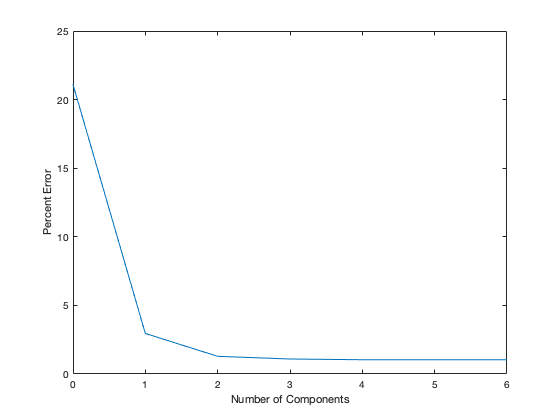

[Xl,Yl,Xs,Ys,beta,pctVar,PLSmsep] = plsregress(X,y,6,"cv",10);
plot(0:6, PLSmsep(2,:))   % row 1 is error in training set
xlabel("Number of Components")
ylabel("Percent Error")

- This plot shows how the error changes with the number of components. 

- It looks like 2 or 3 components is ideal:

[Xl,yl,Xs,Ys,betaPLS,PCTVar] = plsregress(X,y,3);

- Note that PLS adds a column of 1's, so the first value of beta is the intercept.

- Plot the percentage variance explained by each of the 3 components:

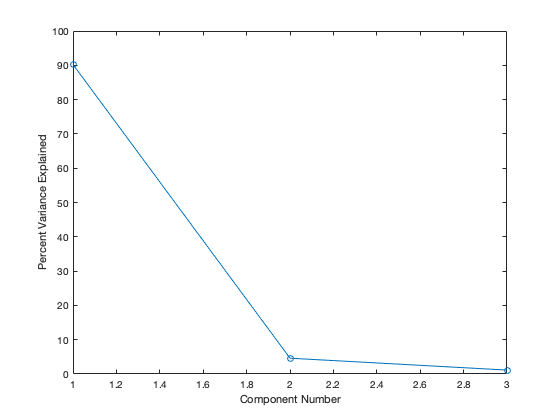

plot(1:3,100*PCTVar(2,:),"-o");
xlabel("Component Number")
ylabel("Percent Variance Explained")

- Compare beta from PLS with other methods.

t = table(B1_coeff, B2(2:end), B3, betaPLS(2:end));
t.Properties.VariableNames = {'Lasso','Normal','Stepwise','PLS'}

t = 6×4 table
     Lasso      Normal      Stepwise      PLS   
    _______    _________    ________    ________

    0.32356      0.81445     0.79653     0.94565
     4.5916       5.0864      5.0376      5.0465
          0      0.10934      0.1531     0.17646
          0     0.057596    0.046956    -0.12674
          0     -0.15156    -0.15944    0.048219
          0    0.0066423    0.084966     0.08098


## Compare Traditional Regression vs Lasso, Stepwise, and PLS in Cleveland data

- Predict disease severity using all variables as input.

- For Lasso and PLS, estimate hyperparameters (lambda) in training data with 3-fold cross validation

- Test accuracy of all methods using 5-fold cross validation - output RMSE and correlation in test set

- Find features that are predicted to be most important using each of these methods.

% Load the Cleveland data set
data = readtable("../cleveland_data_revised.xlsx");

% Remove rows with NaN and separate data into X and y
data = rmmissing(data);
X = data{:,(1:13)};
y = data.diseaseSeverity;

% Create training and test sets
% [trainInd,~,testInd] = dividerand(297,0.7,0,0.3);
% Xtrain = X(trainInd)';
% Xtest = X(testInd)';
% ytrain = y(trainInd);
% ytest = y(testInd);

Before creating the four models, we need to determine the number of components to specify in the PLS model.

[Xl,Yl,Xs,Ys,beta,pctVar,PLSmsep] = plsregress(X,y,10,"cv",3);
plot(0:10, PLSmsep(2,:))   % row 1 is error in training set
xlabel("Number of Components")
ylabel("Percent Error")

It appears that 6 components is adequete for minimizing the error of the PLS model. We can now create a for loop which creates the normal, lasso, stepwise and PLS models.

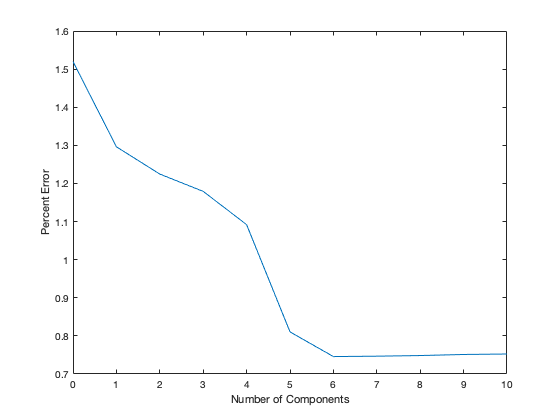

indices = crossvalind("kfold",size(X,1),5);
X_ones = [ones(length(X),1) X];


for i = 1:3
    test = (indices == i);
    train = ~test;
    
    Xtrain = X(train,:);
    X_ones_train = X_ones(train,:);
    ytrain = y(train,:);
   
    
    b_regress = regress(ytrain,X_ones_train);
    
    [b_lasso, Fit] = lasso(Xtrain,ytrain,"CV",3);
    b_lasso_coeff = b_lasso(:,Fit.Index1SE);
    b_lasso_intercept = Fit.Intercept(Fit.Index1SE);
    
    b_stepwise = stepwisefit(Xtrain,ytrain,"display","off");
    
    [Xl,yl,Xs,Ys,b_pls,PCTVar] = plsregress(Xtrain,ytrain,6);
    
    Xtest = X(test,:);
    X_ones_test = X_ones(test,:);
    ytest = y(test,:);
    
    y_regress = X_ones_test(:,2:end)*b_regress(2:end)+b_regress(1);
    y_lasso = Xtest*b_lasso_coeff + b_lasso_intercept;
    y_stepwise = Xtest*b_stepwise;
    y_pls = Xtest*b_pls(2:end)+b_pls(1);
   
    rmse_regress = sqrt(mean(y_regress-ytest)^2);
    rmse_lasso = sqrt(mean(y_lasso-ytest)^2);
    rmse_stepwise = sqrt(mean(y_stepwise-ytest)^2);
    rmse_pls = sqrt(mean(y_pls-ytest)^2);
end
mean(rmse_regress)
mean(rmse_lasso)
mean(rmse_stepwise)
mean(rmse_pls)

ans = 0.0758

ans = 0.1440

ans = 1.9532

ans = 0.0792

## No Free Lunch Theorem

- "No specific ML algorithm is universally superior to any other algorithm."

- If an algorithm performs better than random search on some problems, then it will perform worse than random on other problems.

- What a given algorithm (e.g. decision trees or lasso) gains on one type of classification problems (e.g. classifying images) is offset by its performance on the remaining problems.

## No Free Lunch - take home

- How well any algorithm performs is determined by how well matched the algorithm is with the problem at hand.

- We need to understand the process that generated the data (e.g. what causes diabetes?) to decide which model to use.

- Having domain expertise is important!